# NB-IoT sim script

## nbiot parameters

clear
numSC=12;%number subcarriers, nbiot=12
numSym=420;%number ofdm symbols, nbiot=grouped 7 per frame but more for this sim
SCS=15e3;%subcarrier spacing, nbiot=15kHz
Fs=numSC*SCS;
cpLen=4;
L = 1;  % Upsampling factor



## sim parameters

%data


randomData=true;
enableFilters=true;
%channel
perfectChannel=false;%no  awgn
maxDopplerShift=0e3;
flatDoppler=true;%true: apply same shift to entire signal, false: gradient from +maxShift to -maxShift over length of signal
maxSNR=5; %signal to noise ratio in dB
%loops
nLoops=20;
loopSNR=true;
SNRstepsize=2;
loopDoppler=false;
dopplerStepsize=0.1e3;

plotScatterPlot=true;
plotSpec=true;

## tx

%generate data
dataLength=numSym*numSC*2;% SF bits per symbol
if randomData
    messageBits= randi([0 1],dataLength,1);
else
    symbol=3;%generate symbols with certain value {0-3}
    messageBits=transpose(repmat(dec2bin(symbol,2)-'0',1,numSym*numSC));% -'0' to convert binary string to vector
end
%turn binary vector into vector of qpsk symbols
qpskSymbols=generateQpskSymbols(messageBits)

messageInts =      1
     0
     1
     0
     2
     3
     1
     3
     0
     2


qpskSymbols =   -0.7071 + 0.7071i
   0.7071 + 0.7071i
  -0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 + 0.7071i
  -0.7071 - 0.7071i
   0.7071 + 0.7071i
   0.7071 - 0.7071i


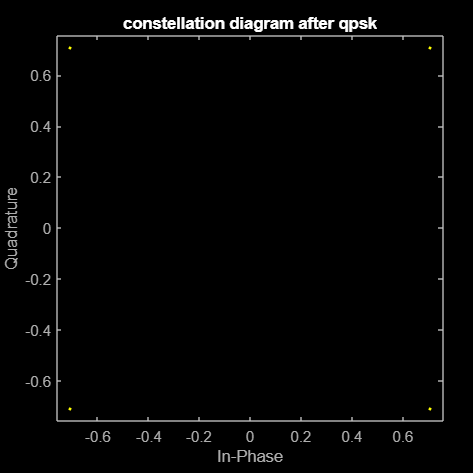


if plotScatterPlot
    %plot scatterplot
    figure;
    scatterplot(qpskSymbols);
    title('constellation diagram after qpsk');
end

% generate ofdm symbols,  numSC samples per symbol in time domain + CP
ofdmTimeSignal=generateOfdmSignal(qpskSymbols,numSC,SCS,cpLen)

ofdmTimeSignal =   -0.1021 + 0.0589i
   0.1179 - 0.1179i
  -0.1336 + 0.0589i
   0.1021 + 0.2630i
   0.0000 + 0.2357i
   0.0705 + 0.2630i
  -0.3378 + 0.0589i
   0.3536 - 0.1179i
   0.1021 + 0.0589i
  -0.5419 - 0.1452i


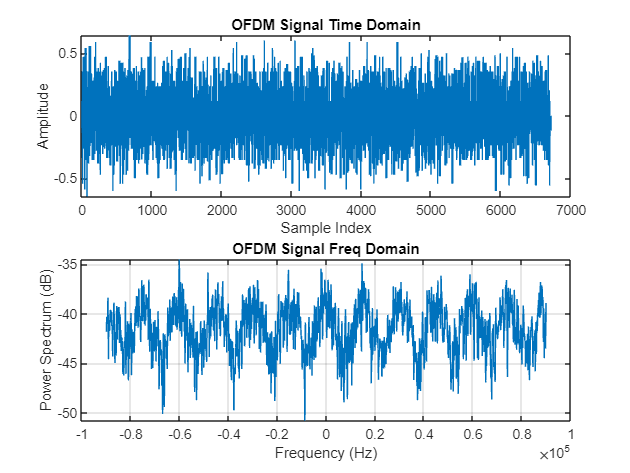


if plotSpec 
    % Plot the time domain signal
    figure;
    subplot(2,1,1);
    plot(real(ofdmTimeSignal));
    title('OFDM Signal Time Domain');
    xlabel('Sample Index');
    ylabel('Amplitude');
    
    [pxx,f] = pspectrum(ofdmTimeSignal,Fs);
    subplot(2,1,2);
    plot(f,pow2db(pxx))
    grid on
    title('OFDM Signal Freq Domain');
    xlabel('Frequency (Hz)')
    ylabel('Power Spectrum (dB)')
end

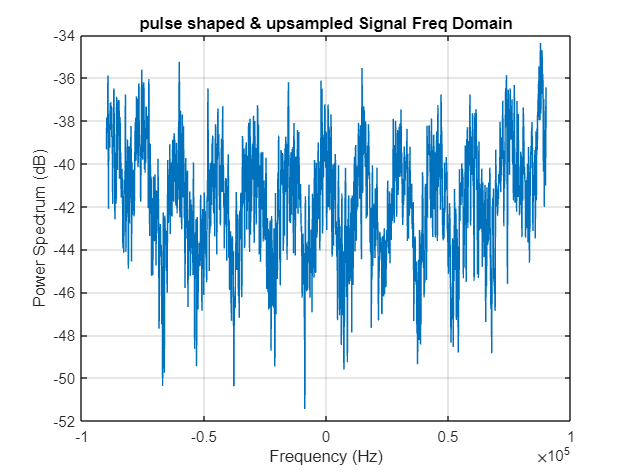


%upsampling & pulse shaping
%L = 2;  % Upsampling factor
rolloff = 0.25;  % Roll-off factor for the RRC filter
span = 10;  % Filter span in symbols

txSignalUpsampled = upsample(ofdmTimeSignal, L);

rrcFilter = rcosdesign(rolloff, span, L);
%impz(rrcFilter)
if enableFilters
    txSignalShaped = conv(txSignalUpsampled, rrcFilter, 'same');
else
    txSignalShaped = txSignalUpsampled;
end

if plotSpec   
    [pxx,f] = pspectrum(txSignalShaped,Fs);
    figure
    plot(f,pow2db(pxx))
    grid on
    title('pulse shaped & upsampled Signal Freq Domain');
    xlabel('Frequency (Hz)')
    ylabel('Power Spectrum (dB)')
end

## channel & rx

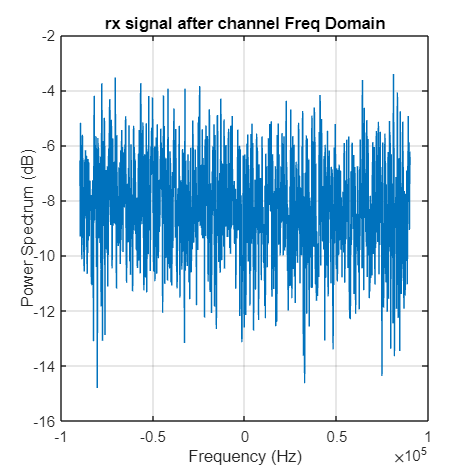

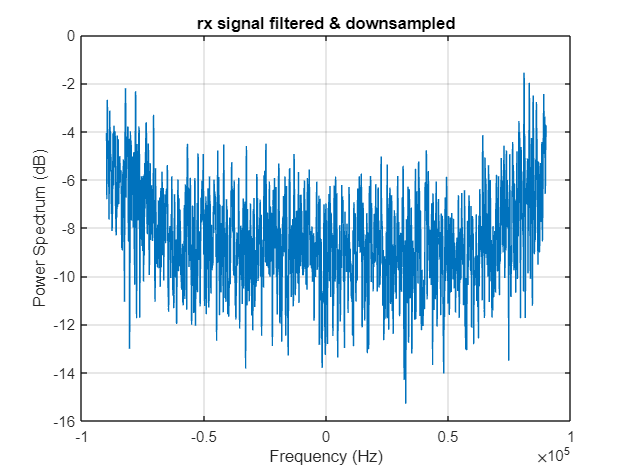

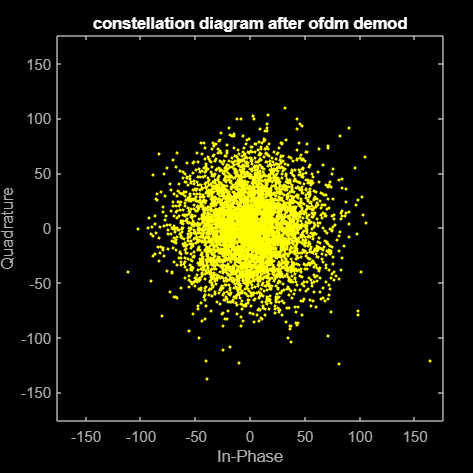

%channel
    symbolDuration = 1 / SCS; % Duration of one OFDM symbol (T=1/FS = 1/SCS)
    SPS=numSC;%samples per ofdm symbol without CP
    if L==1
        t=(symbolDuration/(SPS+cpLen):symbolDuration/(SPS+cpLen):(symbolDuration)*numSym);%time for each sample
    else
        t=(symbolDuration/(SPS+cpLen+(L-1)*(SPS+cpLen)):symbolDuration/(SPS+cpLen+(L-1)*(SPS+cpLen)):(symbolDuration)*numSym);%time for each sample
    end
for counter=1:nLoops
    if loopDoppler
        dopplerShift=maxDopplerShift-dopplerStepsize*(counter-1);
    else
        dopplerShift=maxDopplerShift;
    end
    if flatDoppler
        freqShift=dopplerShift;
    else
        freqShift=linspace(dopplerShift,-dopplerShift,length(t));
    end
    
    dopplerEffect = exp(1i * 2 * pi * freqShift.* t);
    
    txSignalDopplerShifted = transpose(txSignalUpsampled) .* (dopplerEffect);

    if loopSNR
        SNR=maxSNR-SNRstepsize*(counter-1);
    else 
        SNR=maxSNR;
    end
    if perfectChannel
        rxSignal=txSignalDopplerShifted;
    else
        rxSignal=awgn(txSignalDopplerShifted,SNR,'measured');
    end

    %delay spread?

    %plots
    if (plotSpec && counter==nLoops)
        figure
        [pxx,f] = pspectrum(rxSignal,Fs);
        plot(f,pow2db(pxx))
        grid on
        title('rx signal after channel Freq Domain');
        xlabel('Frequency (Hz)')
        ylabel('Power Spectrum (dB)')
    end

    %rx
    if enableFilters
        matchedFilter = rcosdesign(rolloff, span, L);
        rxSignalFiltered = conv(rxSignal, matchedFilter, 'same');
    else
        rxSignalFiltered = rxSignal;
    end
    %downsample
    rxSignalDownsampled = downsample(rxSignalFiltered, L);
    if (plotSpec && counter==nLoops)
        figure
        [pxx,f] = pspectrum(rxSignalDownsampled,Fs);
        plot(f,pow2db(pxx))
        grid on
        title('rx signal filtered & downsampled');
        xlabel('Frequency (Hz)')
        ylabel('Power Spectrum (dB)')
    end
    %demod ofdm
    qpskSymbolsRx=demodOFDM(rxSignalDownsampled, numSC,SCS,cpLen);
    qpskSignalRx=qpskSymbolsRx(:);

    if (plotScatterPlot && counter== nLoops)
        %plot scatterplot
        figure;
        scatterplot(qpskSignalRx);
        title('constellation diagram after ofdm demod');
    end
    %demod qpsk symbols into bits
    demodulatedBits=demodQPSK(qpskSignalRx);

    %error rate
    errors=sum(transpose(demodulatedBits)~=transpose(messageBits(1:dataLength)));
    nbiot_ber(counter)=errors/dataLength;
    symbolRate=Fs/SPS;
    bitRate =  2*12*symbolRate;
    
    SNR_linear = 10^(SNR / 10);
    %Eb_N0(counter) = (SNR_linear * samplingRate) / bitRate
    
    EbN0_sim(counter)=10*log10(SNR_linear*Fs/bitRate);
end

## ber

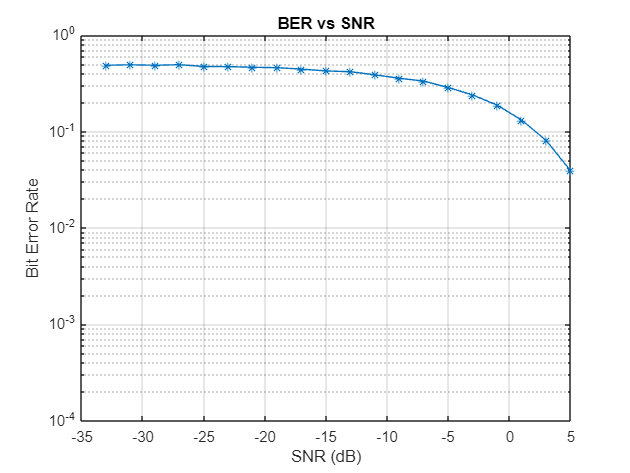

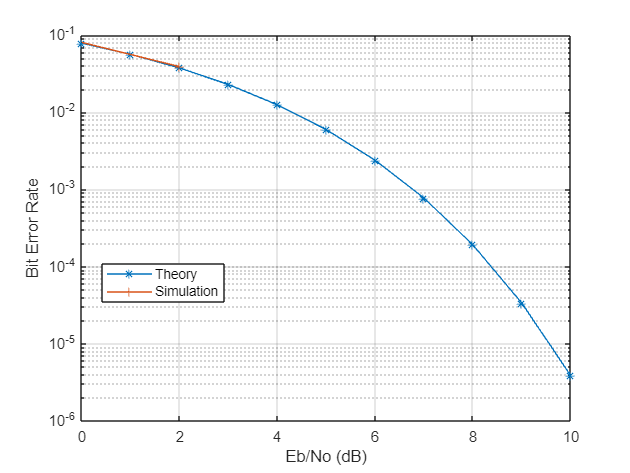

if loopSNR
    EbN0=0:10;
    figure
    SNRvec=flip((maxSNR-(nLoops-1)*SNRstepsize):SNRstepsize:maxSNR);
    semilogy(SNRvec',nbiot_ber,'-*')
    grid on
    xlabel('SNR (dB)')
    ylabel('Bit Error Rate')
    ylim([10e-5 1])
    title('BER vs SNR')
    
    %EbN0=(10*log10(maxSNR-(SNRstepsize*(nLoops-1))*Fs/bitRate):10*log10(maxSNR*Fs/bitRate));
    ber=berawgn(EbN0,"psk",4,"nondiff");
    figure
    semilogy(transpose(EbN0),ber,'-*')
    hold on
    semilogy(transpose(EbN0_sim),nbiot_ber,'-+')
    legend({'Theory','Simulation'},'Location','best')
    xlabel('Eb/No (dB)')
    ylabel('Bit Error Rate')
    xlim([0,inf]);
    grid on
end